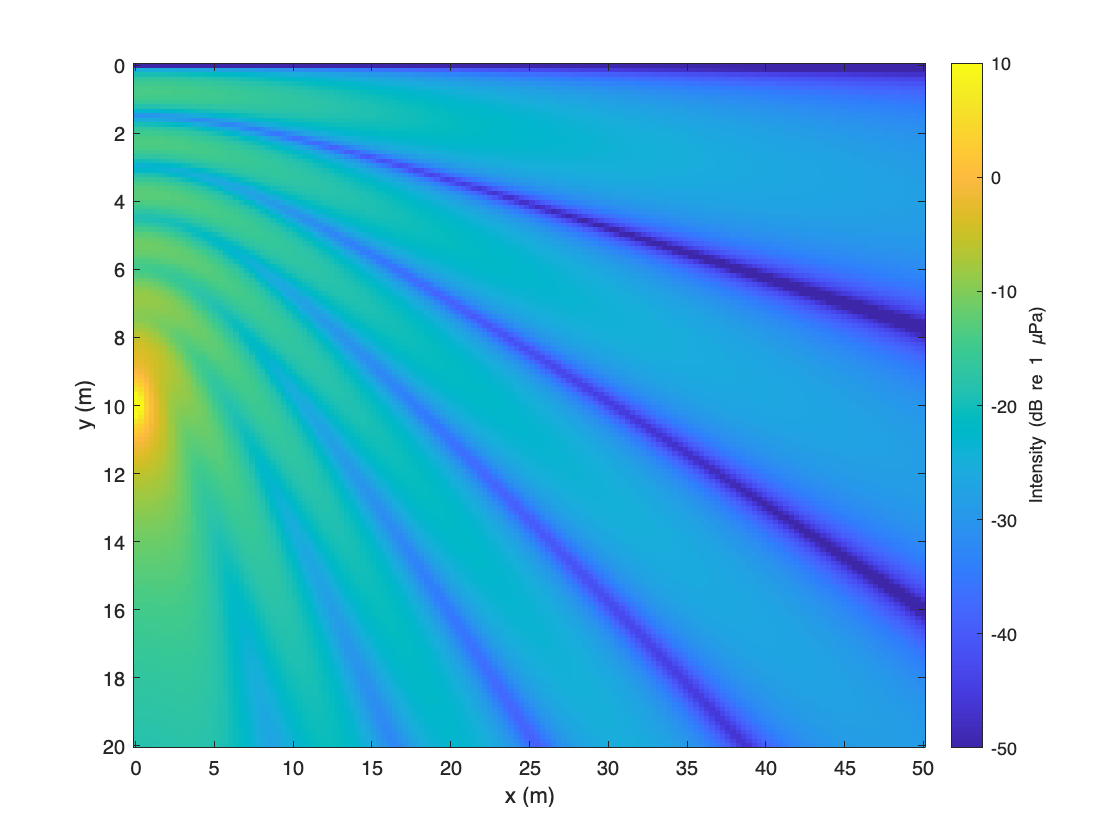

f = 500; % frequency in Hz
d = 10; % Source Depth
c = 1500 ; % Speed of sound (m/s)


dmax = 10; % depth of source
Lx = 5*dmax; % horizontal extent of calculation
Ly = 2*dmax; % vertical extent of calculation
Nx = 150; % Number of points in horizontal calculation
Ny = Nx;
x = linspace(0,Lx,Nx);
y = linspace(0,Ly,Ny);

SL = 0; % SL is 0 dB
A_SL = 10^(SL/20); % pressure amplitude of source (microPascal)

[X,Y] = meshgrid(x,y);

r1 = sqrt(X.^2 + (Y-d).^2); % Range from source
r2 = sqrt(X.^2 + (Y+d).^2); % Range from virtual source

p1 = A_SL.*exp(1i*2*pi*f*r1/c)./r1; % Pressure due to source
p2 = -A_SL.*exp(1i*2*pi*f*r2/c)./r2; % Pressure due to virtual source
p = p1 + p2; % Coherent sum of source and virtual source

plotType = 1;

if plotType == 0
    imagesc(x,y,real(p)*sqrt(2)) % Plot the pressure
    a = gca;
    a.XLabel.String = 'x (m)';
    a.YLabel.String = 'y (m)';
    c1 = colorbar;
    c1.Label.String = 'Pressure (\muPa)';

elseif plotType == 1
    imagesc(x,y,20*log10(abs(p))) % Plot the intensity
    a = gca;
    a.XLabel.String = 'x (m)';
    a.YLabel.String = 'y (m)';
    c1 = colorbar;
    c1.Label.String = 'Intensity (dB re 1 \muPa)';
    a.CLim = [-50 10];
else 

    imagesc(x,y,angle(p)) % Plot the phase of the pressure
    a = gca;
    a.XLabel.String = 'x (m)';
    a.YLabel.String = 'y (m)';
    c1 = colorbar;
    c1.Label.String = 'Phase (radians)';

end